**Control structures (conditionals and loops)**

**Analysis for Neuroscientists**

**September 26, 2022**

**1 Conditional Statements**

Beside *if-else* statements we can use *case-switch-otherwise*

The code will look like:

choice = 3;
switch choice
    case 1
        x = -pi:0.01:pi;
    case 2
        x = 0:1:physconst('earthradius');
    otherwise
        % does not know anything about x
end

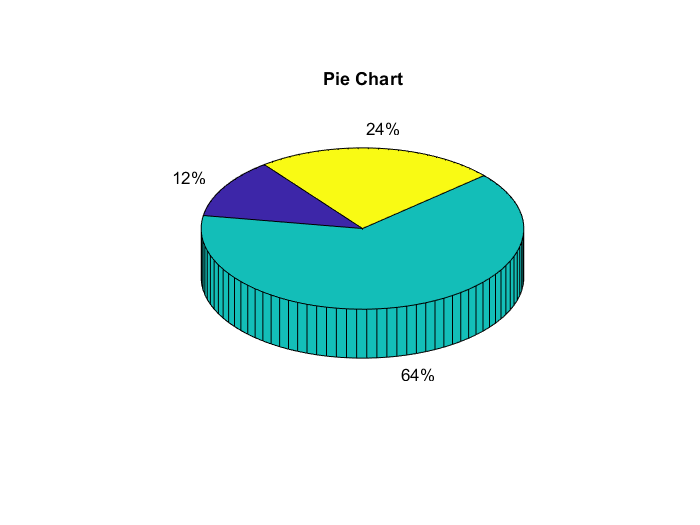

x = [12 64 24];
plottype = 'pie';

switch plottype
    case 'bar' 
        bar(x)
        title('Bar Graph')
    case {'pie','pie3'}
        pie3(x)
        title('Pie Chart')
    otherwise
        warning('Unexpected plot type. No plot created.')
end

C = {1,2,3;
     'text',rand(5,10,2),{11; 22; 33}}

C = 2×3 cell array
    {[   1]}    {[          2]}    {[     3]}
    {'text'}    {5×10×2 double}    {3×1 cell}


**2 Loop Control Statements**

The use of nested loops is common when traversing data structures (as well as in other situations). We should practice using it.  

disp('outer loop  inner loop')

outer loop  inner loop


for ii = 1:7
 % do work in outer loop
 % ...
 disp(num2str(ii))
   for jj = 1:3
   % do work in inner loop
   % ...
   disp(num2str([ii jj]))
   end
end

1


1  1
1  2
1  3


2


2  1
2  2
2  3


3


3  1
3  2
3  3


4


4  1
4  2
4  3


5


5  1
5  2
5  3


6


6  1
6  2
6  3


7


7  1
7  2
7  3


Let's look at the game Sudoku to see how nested loops can help us design a MATLAB version of the game. 

sudokuPuzzle = [1 1 0 0 1 0 0 0 0 ; ...
				1 0 0 1 1 1 0 0 0 ; ...
				0 1 1 0 0 0 0 1 0 ; ...
				1 0 0 0 1 0 0 0 1 ; ...
				1 0 0 1 0 1 0 0 1 ; ...
				1 0 0 0 1 0 0 0 1 ; ...
				0 1 0 0 0 0 1 1 0 ; ...
			    0 0 0 1 1 1 0 0 1 ; ...
                0 0 0 0 1 0 0 1 1];
 
sudokuAnswer = [5 3 4 6 7 8 9 1 2 ; ...
				6 7 2 1 9 5 3 4 8 ; ...
				1 9 8 3 4 2 5 6 7 ; ...
				8 5 9 7 6 1 4 2 3 ; ...
				4 2 6 8 5 3 7 9 1 ; ...
				7 1 3 9 2 4 8 5 6 ; ...
				9 6 1 5 3 7 2 8 4 ; ...
			    2 8 7 4 1 9 6 3 5 ; ...
                3 4 5 2 8 6 1 7 9];

The first thing we would like to do is display the puzzle but in a stylistic manner using “character graphics.” 

Maybe something like the following: 

% _________________________
% | 5 3 _ | _ 7 _ | _ _ _ |
% | 6 _ _ | 1 9 5 | _ _ _ |
% | _ 9 8 | _ _ _ | _ 6 _ |
% _________________________
% | 8 _ _ | _ 6 _ | _ _ 3 |
% .
% .
% .
% _________________________
disp('_________________________')   
for k = 1:3
    for i = 1:3
        dispOutput = ['|'];
        for j = 1:3
            if sudokuPuzzle(3*(k-1)+i, j) == 1
                dispOutput = [dispOutput ' ' num2str(sudokuSolution(3*(k-1)+i,j))];
            else
                dispOutput = [dispOutput ' ' '_'];
            end            
        end
        dispOutput = [dispOutput ' ' '|'];
        for j = 4:6
            if sudokuPuzzle(3*(k-1)+i, j) == 1
                dispOutput = [dispOutput ' ' num2str(sudokuSolution(3*(k-1)+i,j))];
            else
                dispOutput = [dispOutput ' ' '_'];
            end            
        end
        dispOutput = [dispOutput ' ' '|'];
        for j = 7:9
            if sudokuPuzzle(3*(k-1)+i, j) == 1
                dispOutput = [dispOutput ' ' num2str(sudokuSolution(3*(k-1)+i,j))];
            else
                dispOutput = [dispOutput ' ' '_'];
            end            
        end
        dispOutput = [dispOutput ' ' '|'];
        disp(dispOutput)
    end
    disp('_________________________')
end

_________________________


| 5 3 _ | _ 7 _ | _ _ _ |


| 6 _ _ | 1 9 5 | _ _ _ |


 _ 9 8 | _ _ _ | _ 6 _ |


_________________________


| 8 _ _ | _ 6 _ | _ _ 3 |
| 4 _ _ | 8 _ 3 | _ _ 1 |


| 7 _ _ | _ 2 _ | _ _ 6 |


_________________________


 _ 6 _ | _ _ _ | 2 8 _ |
 _ _ _ | 4 1 9 | _ _ 5 |


 _ _ _ | _ 8 _ | _ 7 9 |


_________________________


Now let's exapnd this to the entire board:

% Similar to what we've done above, we would like to traverse the board
% moving to the next 3x3 section. How can we integrate the vertical and
% the horizontal bars?

Now we would like to start thinking about letting the user enter numbers into the board.

 First, we will prepare a new variable to contain the player's moves. 

sudokuMyAnswer = sudokuAnswer .* sudokuPuzzle

sudokuMyAnswer =      5     3     0     0     7     0     0     0     0
     6     0     0     1     9     5     0     0     0
     0     9     8     0     0     0     0     6     0
     8     0     0     0     6     0     0     0     3
     4     0     0     8     0     3     0     0     1
     7     0     0     0     2     0     0     0     6
     0     6     0     0     0     0     2     8     0
     0     0     0     4     1     9     0     0     5
     0     0     0     0     8     0     0     7     9


Next, we would like to use LiveScript functionality to enter numbers in different locations. 

How would a code to ask for entering a number would look like?

row = 2;
column = 3;
value = 6;

if (sudokuMyAnswer(row, column) == 0)
   sudokuMyAnswer(row, column) = value
else
    disp(['In row ' num2str(row) ' column ' num2str(column) ' there is already a value'])
end

sudokuMyAnswer =      5     3     0     0     7     0     0     0     0
     6     0     0     1     9     5     0     0     0
     0     9     8     0     0     0     0     6     0
     8     0     0     0     6     0     0     0     3
     4     0     0     8     0     3     0     0     1
     7     0     6     0     2     0     0     0     6
     0     6     0     0     0     0     2     8     0
     0     0     0     4     1     9     0     0     5
     0     0     0     0     8     0     0     7     9
